 clc
clear
alpha = 0;
t_end = 4;
Ts = 1/100;
load("K.mat")

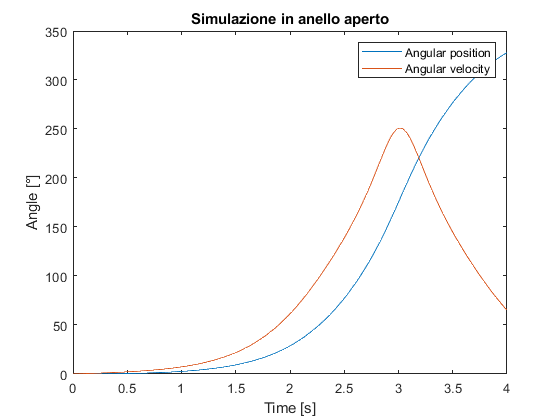

control_on = 0;
sim  VABSim_n_l.slx;
phi = q(:,1);
phi_p = q(:,2);
theta = q(:,3);
theta_p = q(:,4);
figure
plot(tout, theta)
xlabel('Time [s]')
ylabel('Angle [°]')
%yline(180,'--','180°','linewidth',2);
title('Simulazione in anello aperto')
hold on
plot(tout,theta_p);
legend('Angular position','Angular velocity')

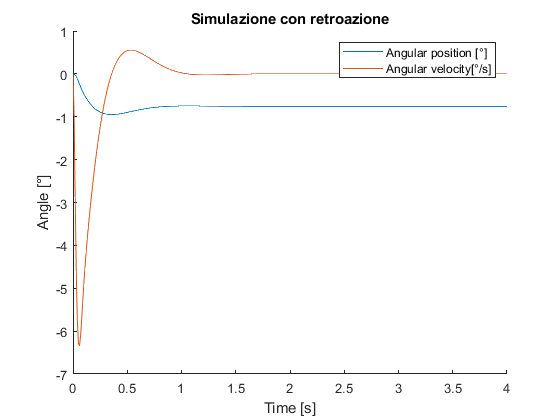

control_on = 1;
sim VABSim_n_l.slx 
phi = q(:,1);
phi_p = q(:,2);
theta = q(:,3);
theta_p = q(:,4);
figure
hold on
plot(tout, theta)
xlabel('Time [s]')
ylabel('Angle [°]')
title('Simulazione con retroazione')
hold on
plot(tout,theta_p);
legend('Angular position [°]','Angular velocity[°/s]')